# Taller Filtros - Parte 3

#### Ana Sofia Aponte Barriga

#### Daniel Esteban Prieto Jiménez

#### José Alejandro Peñaranda Chia

# Filtros FIR

### Creación de los filtros

Inicialmente se calculará el orden de todos los filtros para definir el orden a usar, que será el orden mayor.

#### G1

[N1, Wn1] = buttord(125*2*pi, 250*2*pi, 3, 15, 's')

N1 = 3

Wn1 = 888.0671

#### G2

[N2, Wn2] = buttord([125*2*pi, 500*2*pi], [62.5*2*pi, 1000*2*pi], 3, 15, 's')

N2 = 2

Wn2 = 	1.0e+03 *

    0.7567    3.2607


#### G3

[N3, Wn3] = buttord([500*2*pi, 2000*2*pi], [250*2*pi, 4000*2*pi], 3, 15, 's')

N3 = 2

Wn3 = 	1.0e+04 *

    0.3027    1.3043


#### G4

[N4, Wn4] = buttord([2000*2*pi, 8000*2*pi], [1000*2*pi, 16000*2*pi], 3, 15, 's')

N4 = 2

Wn4 = 	1.0e+04 *

    1.2107    5.2172


#### G5

[N5, Wn5] = buttord(8000*2*pi, 4000*2*pi, 3, 15, 's')

N5 = 3

Wn5 = 4.4454e+04

N1, N2, N3, N4, N5

N1 = 3

N2 = 2

N3 = 2

N4 = 2

N5 = 3

El orden mayor es 3, por lo tanto se diseñarán filtros Butterworth de orden 3 en todos los casos. G1 será pasabajos, G5 pasaaltos y los demás serán pasabanda.

N = 3 ;

#### G1

[num1, den1] = butter(N, Wn1,'low', 's')

num1 = 	1.0e+08 *

         0         0         0    7.0039


den1 = 	1.0e+08 *

    0.0000    0.0000    0.0158    7.0039


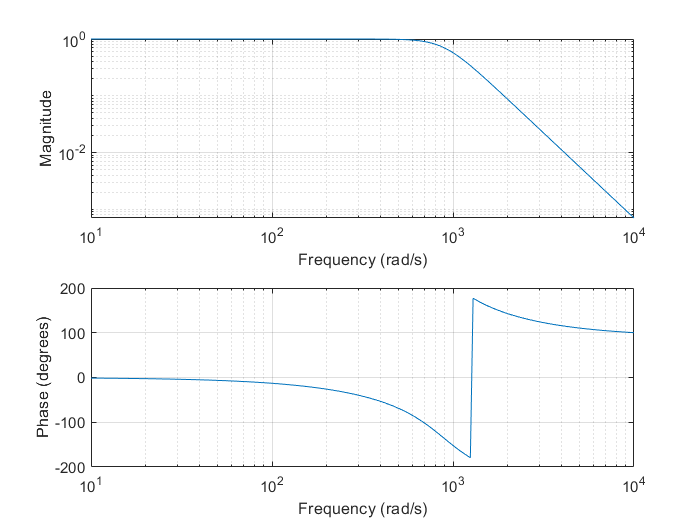

freqs(num1, den1)

#### G2

[num2, den2] = butter(N, Wn2,'bandpass', 's')

num2 = 	1.0e+10 *

         0         0         0    1.5701         0         0         0


den2 = 	1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0030    1.5022


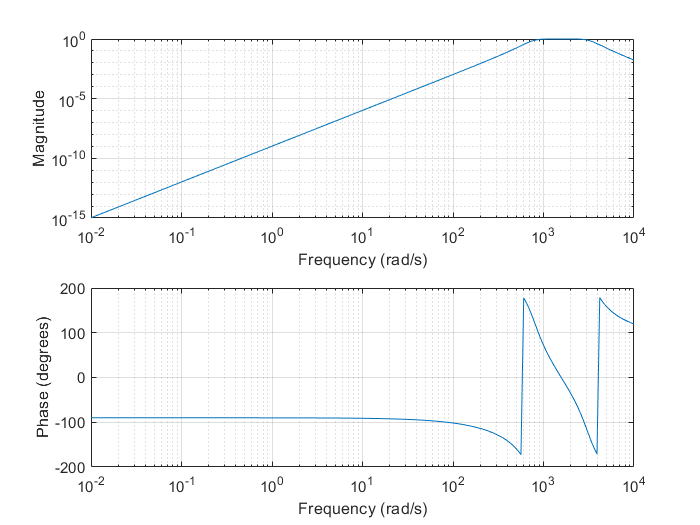

freqs(num2, den2)

#### G3

[num3, den3] = butter(N, Wn3,'bandpass', 's')

num3 = 	1.0e+12 *

         0         0         0    1.0048         0         0         0


den3 = 	1.0e+22 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0031    6.1529


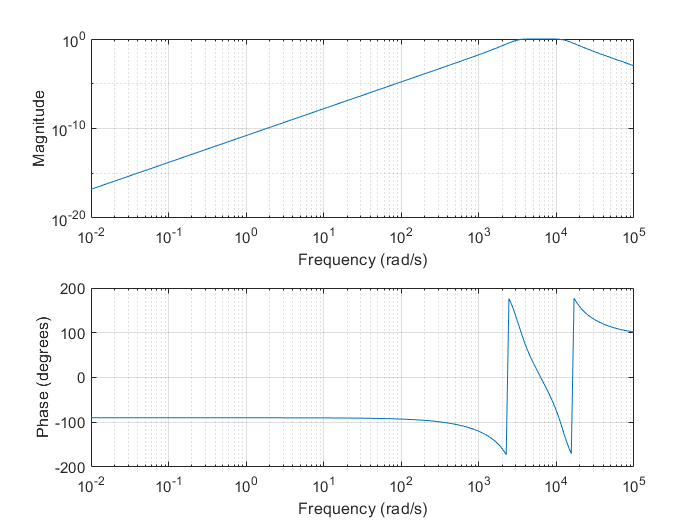

freqs(num3, den3)

#### G4

[num4, den4] = butter(N, Wn4,'bandpass','s')

num4 = 	1.0e+13 *

         0         0         0    6.4310         0         0         0


den4 = 	1.0e+26 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    2.5202


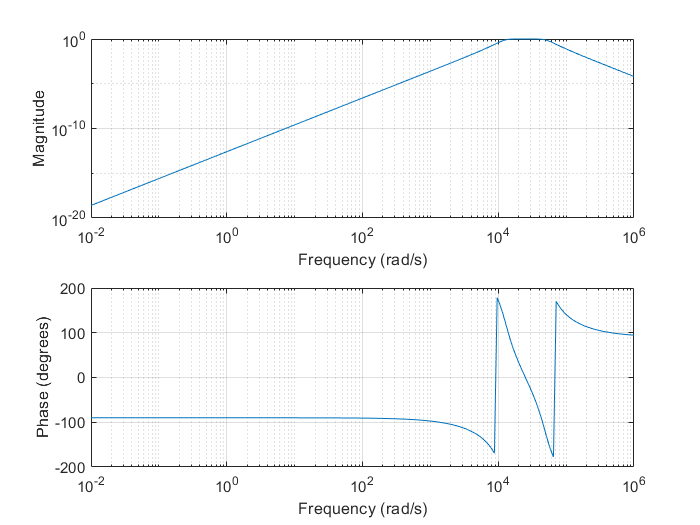

freqs(num4, den4)

#### G5

[num5, den5] = butter(N, Wn5, 'high', 's')

num5 =      1     0     0     0


den5 = 	1.0e+13 *

    0.0000    0.0000    0.0004    8.7850


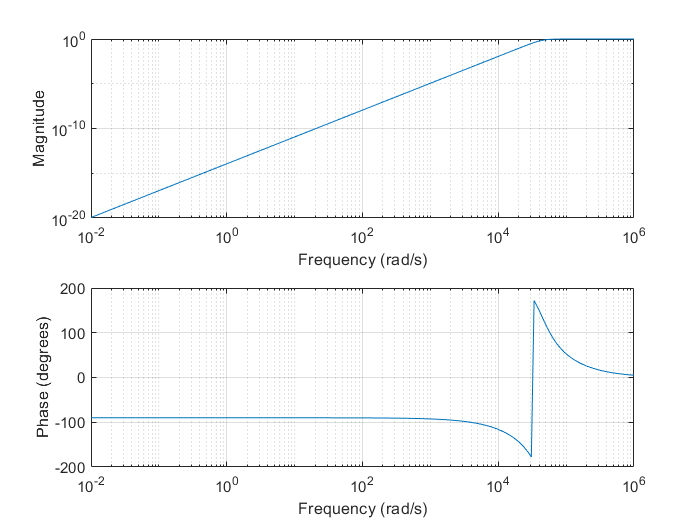

freqs(num5, den5)

Se cargan las variables requeridas:

fsAudio = 64000 ;
load Audio1.mat
load Audio2.mat
[Audio3, fsmp3] = audioread("jour-1.mp3") ; % Acá se cambia el mp3
Audio3 = Audio3(:, 1) ;

### Espacio para seleccionar el audio

prueba = Audio3 ;
fs = fsmp3 ;

Se plotea la parte inicial de la señal de entrada para tener una idea más clara de la forma de esta:

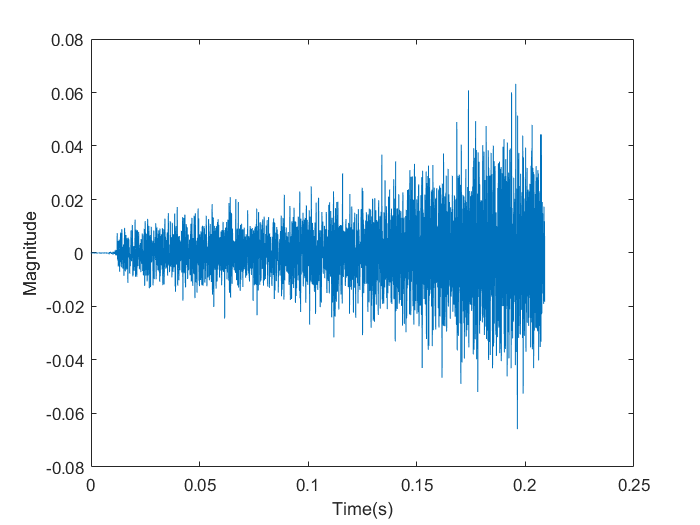

len = size(prueba, 1) ;
T = linspace(0, ceil(len/fs), len)' ;
plot(T(1:10000, 1), prueba(1:10000, 1))
xlabel('Time(s)')
ylabel('Magnitude')

En el caso de los archivos de prueba Audio1 y Audio2 la frecuencia de muestreo es 64000 y la longitud del vector de entrada es 640000 entonces el tiempo total será:


$$T=\frac{640000}{64000}=10\;s$$


el vector T tiene la misma longitud del vector de audio.

### Implementación de los filtros

Se crea un sistema con cada filtro y se aplica a la señal de entrada:

#### G1

sys1 = tf(num1, den1)

sys1 =
 
                 7.004e08
  --------------------------------------
  s^3 + 1776 s^2 + 1.577e06 s + 7.004e08
 
Continuous-time transfer function.



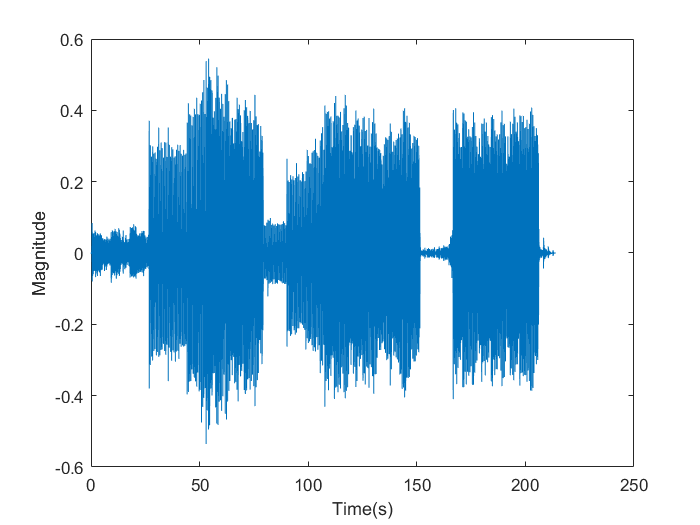

y1 = lsim(sys1, prueba, T);
plot(T, y1)
xlabel('Time(s)')
ylabel('Magnitude')

#### G2

sys2 = tf(num2, den2)

sys2 =
 
                                      1.57e10 s^3
  -----------------------------------------------------------------------------------
  s^6 + 5008 s^5 + 1.994e07 s^4 + 4.041e10 s^3 + 4.921e13 s^2 + 3.049e16 s + 1.502e19
 
Continuous-time transfer function.



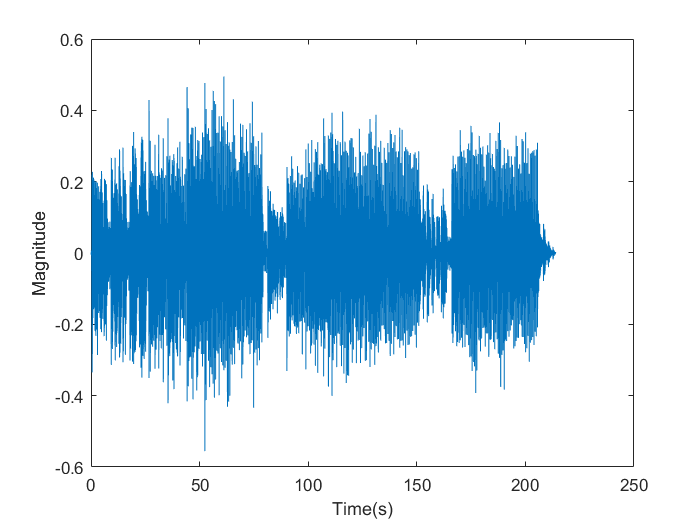

y2 = lsim(sys2, prueba, T);
plot(T, y2)
xlabel('Time(s)')
ylabel('Magnitude')

#### G3

sys3 = tf(num3, den3)

sys3 =
 
                                       1.005e12 s^3
  --------------------------------------------------------------------------------------
  s^6 + 2.003e04 s^5 + 3.191e08 s^4 + 2.587e12 s^3 + 1.26e16 s^2 + 3.122e19 s + 6.153e22
 
Continuous-time transfer function.



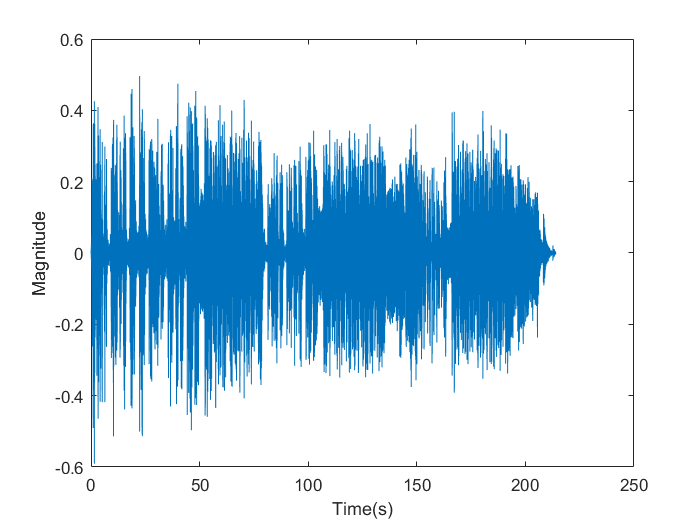

y3 = lsim(sys3, prueba, T);
plot(T, y3)
xlabel('Time(s)')
ylabel('Magnitude')

#### G4

sys4 = tf(num4, den4)

sys4 =
 
                                       6.431e13 s^3
  --------------------------------------------------------------------------------------
  s^6 + 8.013e04 s^5 + 5.105e09 s^4 + 1.655e14 s^3 + 3.225e18 s^2 + 3.197e22 s + 2.52e26
 
Continuous-time transfer function.



y4 = lsim(sys4, prueba, T);
plot(T, y4)
xlabel('Time(s)')
ylabel('Magnitude')

#### G5

sys5 = tf(num5, den5)

sys5 =
 
                     s^3
  ------------------------------------------
  s^3 + 8.891e04 s^2 + 3.952e09 s + 8.785e13
 
Continuous-time transfer function.



y5 = lsim(sys5, prueba, T);
plot(T, y5)
xlabel('Time(s)')
ylabel('Magnitude')

#### Ganancias

Finalmente se eligen los valores de las ganancias para combinar las señales de salida de los filtros:

G1 = 1; % 62.5Hz
G2 = 1; % 250Hz
G3 = 1; % 1kHz
G4 = 1; % 4kHz
G5 = 1; % 16kHz

  G1 = 1 ; G2 = 1 ; G3 = 1 ; G4 = 1 ; G5 = 1 ;

  G1 = 1 ; G2 = 1 ; G3 = 1.3 ; G4 = 0.6 ; G5 = 0.6 ;

  G1 = 1 ; G2 = 0.4 ; G3 = 1.1 ; G4 = 1.6 ; G5 = 1.6 ;

  G1 = 1 ; G2 = 1.5 ; G3 = 0.8 ; G4 = 0.9 ; G5 = 0.9 ;

  G1 = 1 ; G2 = 1.3 ; G3 = 0.8 ; G4 = 1.3 ; G5 = 1.3 ;

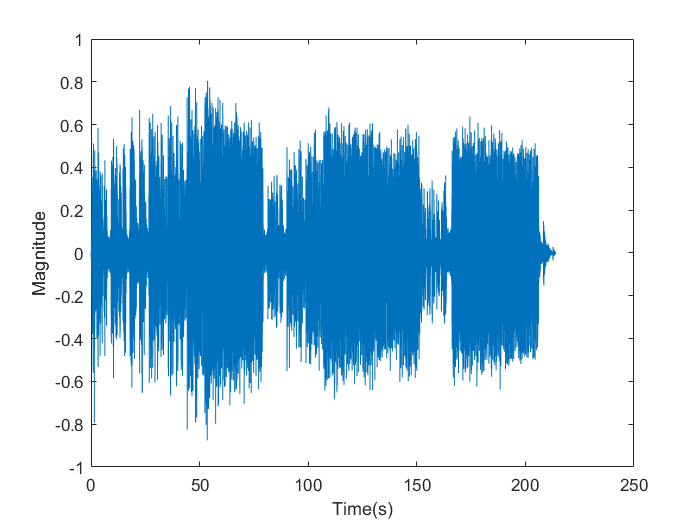

 
Y = G1*y1+G2*y2+G3*y3+G4*y4+G5*y5 ;
plot(T, Y)
xlabel('Time(s)')
ylabel('Magnitude')

 
if max(abs(Y)) > 1
    Y = Y/max(abs(Y)) ;
end
player = audioplayer(Y, fs)

player =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 10244208
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


play(player)

  stop(player) 